# 9. Исследование маятника Капицы

**Цель**: научиться проводить эксперименты с моделями в Simulink

Мы с вами научились строить простые модели в Simulink. Построенная модель это только начало работы инженера, так как модель строится для того, чтобы исследовать какое-либо явление. Программная модель позволяет нам полностью автоматизировать процесс исследования, мы можем в цикле перебирать разные параметры модели, ставить условия на их измненение и отбор нужных нам результатов.

Модель математического маятника не так интересна для исследования, поэтому на этом занятии предлагаем построить вам модель маятника капицы и исследовать его

## 1 Физическое явление

**Маятником Капицы** называется система, состоящая из грузика, прикрепленного к легкой нерастяжимой спице, которая крепится к вибрирующему подвесу. У математического маятника есть два положения равновесия 0 и 180 градусов и второе является неустойчивым. Для маятника Капицы же неустойчивое положение равновесия может становится устойчивым в случае быстрых вибраций точки подвеса.

## 2 Физическая модель

На рисунке ниже представлена схема физического явления маятника с вибрирующим подвесом

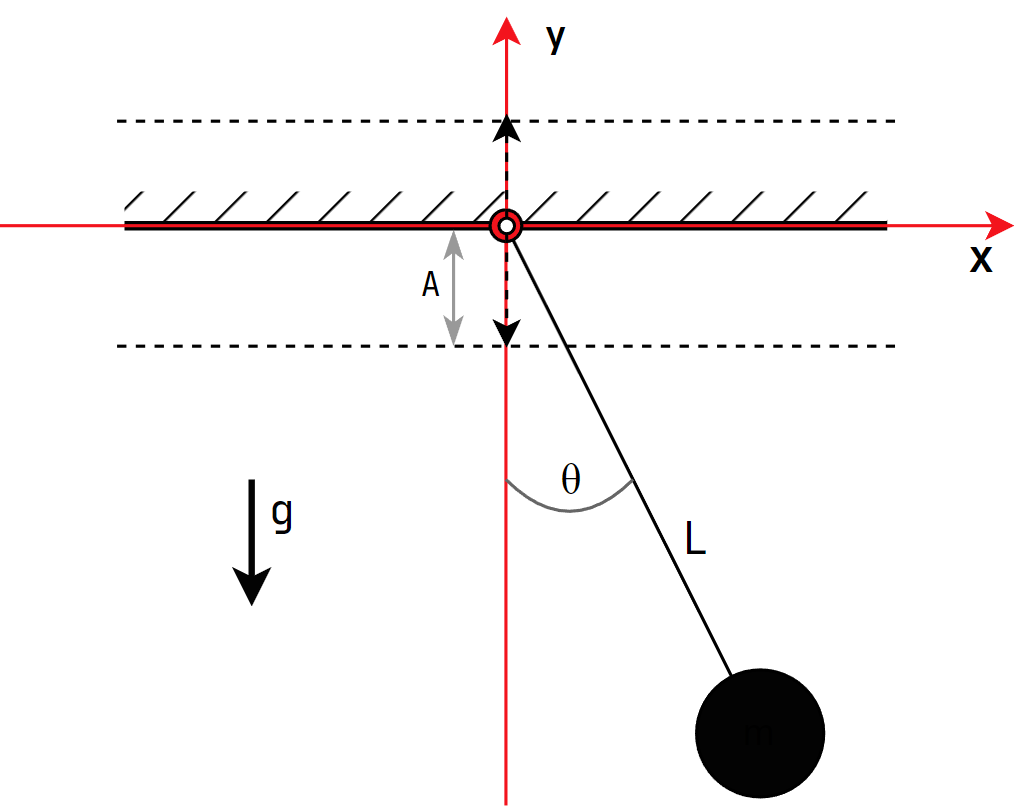

Тогда координаты грузика:


$$
\left\{
\begin{array}{@{}ll@{}}
x = L\sin{\theta}
\\
y = -L\cos{\theta}-A\cos{\omega t} 
\end{array}$$


Здесь:

- g -- ускорение свободного падения

- $\theta
$-- угол отклонения маятника

- L -- длина спицы

- $\omega$ -- частота колебаний подвеса

- A -- амплитуда колебаний подвеса

## 3 Математическая модель

Для расчёта уравнений движения воспользуемся Уравнениями Эйлера-Лагранажа для движения механической системы. Сначала рассчитаем потенциальную и кинетическую энергию системы


$$E_P = -mg(l\cos{\theta} + A\cos{\omega t})$$



$$E_K = \frac{m(\dot{x}+\dot{y})}{2}$$


Тогда лагранжиан системы:


$$L = E_K - E_P$$


Подставив его в уравнение Эйлера-Лагранжа (мы опустим здесь полные расчёты, но можете выполнить их самостоятельно):


$$\frac{d}{dt} \frac{\partial L}{\partial \dot\theta} = \frac{\partial L}{\partial \theta}$$


Подставив и упростив уравнение получим:


$$I \ddot \theta = -b\dot\theta - ml(g + A\omega^2\cos{\omega t})\sin{\theta}$$


Данное уравнение будет выступать основным для создания модели маятника капицы.

## 4 Исполнение модели из скрипта

Поскольку Simulink и MATLAB находятся в одном пространтве мы можем выполнять модель прямо из кода MATLAB и менять параметры через перменные в рабочей среды. Попробуем выполнить модель `simple_model.slx, `в которой есть только блок генерации синусоидального сигнала. Попробуем сгенерировать колебание с разными параметрами, которые будут изменяться из скрипта.

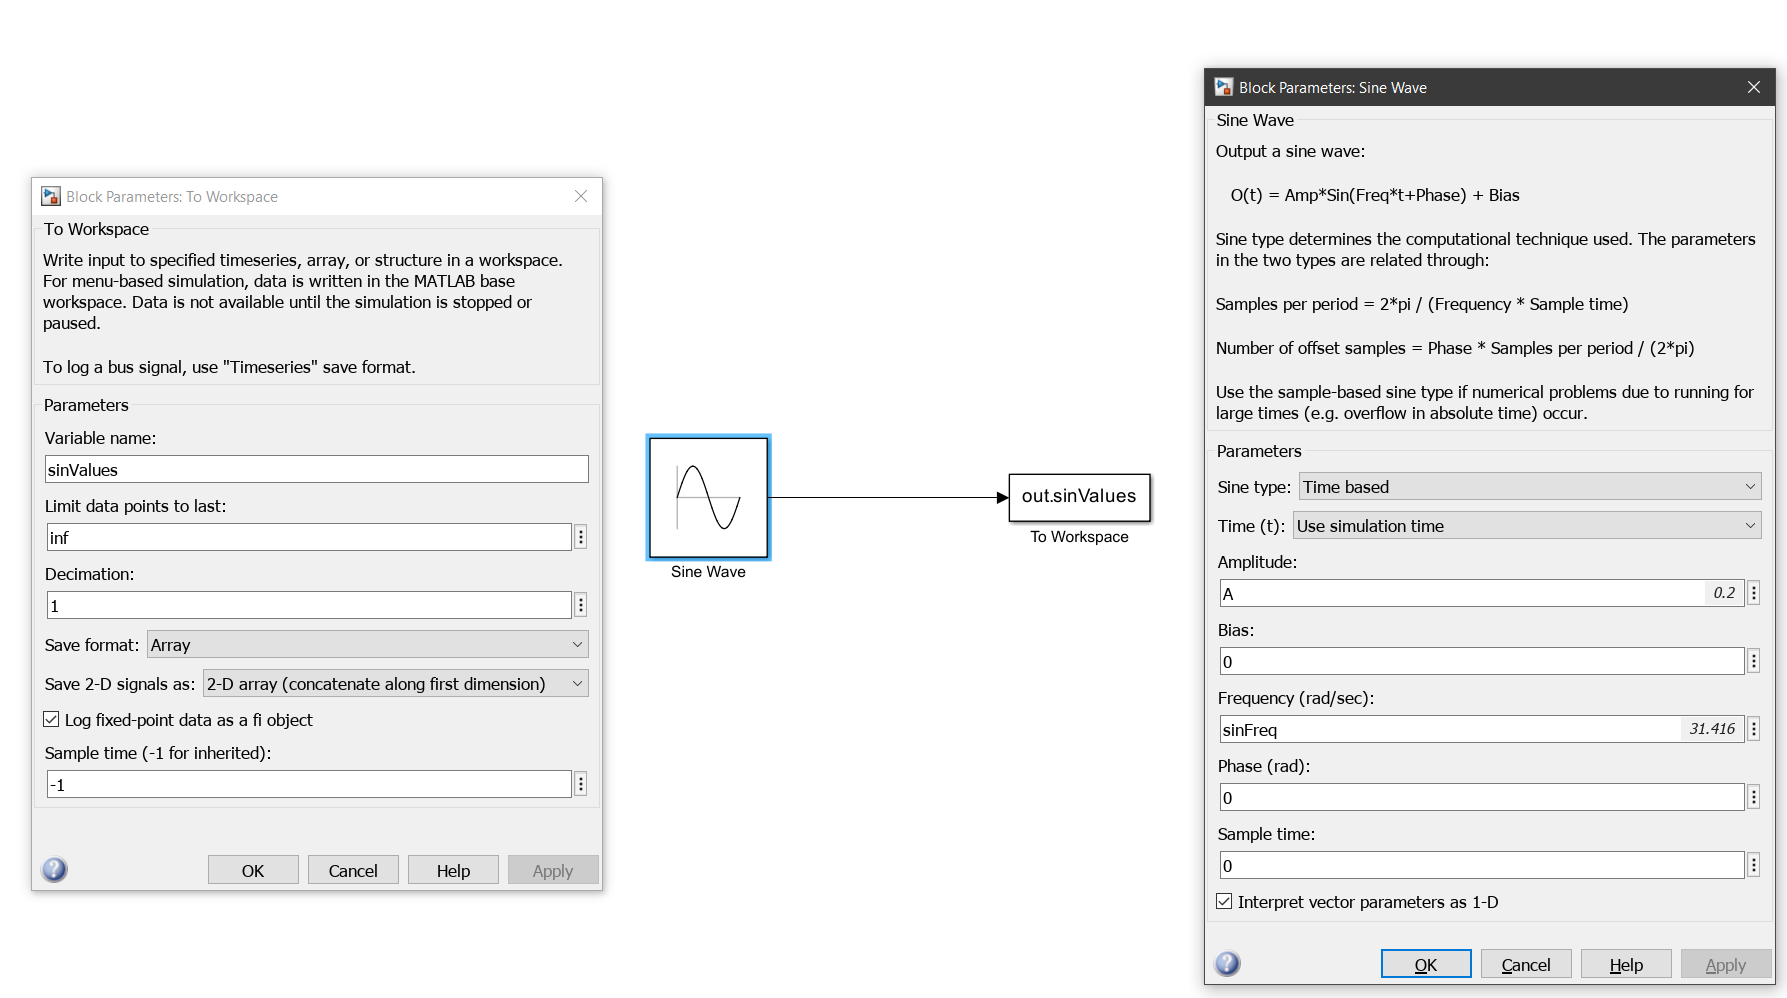

Для вывода данных из скрипта, мы воспользуемся блоком `To Workspace. `Все параметры блоков приведены на рисунках выше.

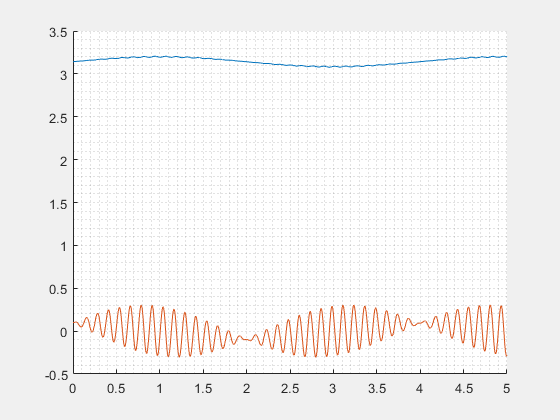

sinFreqsHz = (1 : 5);

close all;
fig1 = figure();
set(fig1,'Visible','on');
hold all;
grid('minor');
title('');




f = 50;
A = 0.1;
theta0 = pi;
m=1;
l=1;
I = m*l^2;
g=10;
out = sim('kapitsa.slx',5); 
plot(out.tout, out.theta);
plot(out.tout, out.dtheta);

fig = figure();
hold all
plot(out.theta, out.dtheta);
f = 10

f = 10

theta0 = 0

theta0 = 0

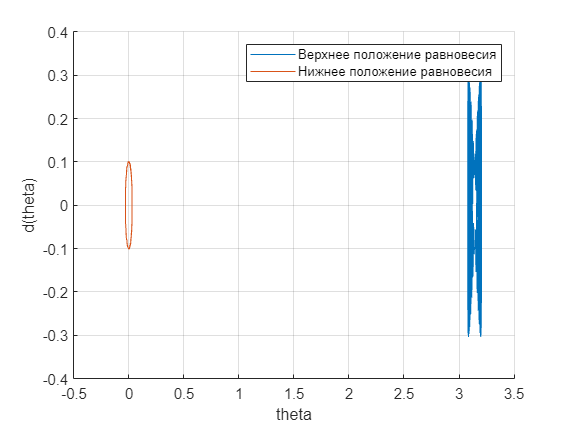

out = sim('kapitsa.slx',5); 
plot(out.theta, out.dtheta);
grid on
xlabel('theta')
ylabel('d(theta)')
legend('Верхнее положение равновесия', 'Нижнее положение равновесия')

f=figure();
hold all
f_s = (l/g)^0.5

f_s = 0.3162

theta0 = 170 * 2*pi/180;

f = 0.001*f_s

f = 3.1623e-04

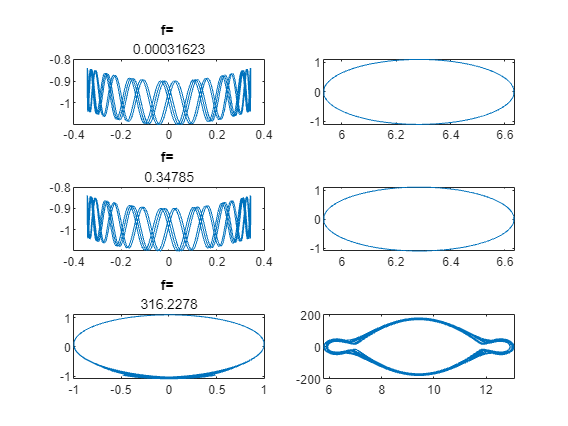

subplot(3,2,1);

out = sim('kapitsa.slx',5); 
plot(out.x, out.y)
title('f= ', string(f))
subplot(3,2,2)
plot(out.theta, out.dtheta)



f=1.1*f_s;
subplot(3,2,3);
out = sim('kapitsa.slx',5); 
plot(out.x, out.y)
title('f= ', string(f))
subplot(3,2,4)
plot(out.theta, out.dtheta)


f = 1000*f_s;
subplot(3,2,5);
out = sim('kapitsa.slx',5); 
plot(out.x, out.y)
title('f= ', string(f))
subplot(3,2,6);
plot(out.theta, out.dtheta)

## Задание

Добавить в модель предыдущего занятия моделирование колбеаний точки подвеса и исследовать данную модель. Найти такие параметры системы, при которых у маятника появляется новое положение устойчивого равновесия.

### Задание 1. Построение модели маятника Капицы

- создать модель Simulink `kapitsa-pendulum.slx` как копию модели `pendulum.slx`;

- написать в комментарий модели уравнение, для маятника Капицы

- добавить в модель подсистему** "Колебания подвеса"** и добавить туда блок `Sin Wave`, который будет моделировать изменение положения точки подвеса

- добавить два выхода: **"Координата подвеса"** и **"Ускорение подвеса"**, которые обозначают координату точки подвеса и ее ускорение соответственно

- создать маску для этой подсистемы и определить в маске параметры **"Амплитуда колебаний"** и **"Частота колебаний"**

- амплитуда должна задаваться в м, а частота в герцах.

- внести данные параметры в блок `Sin Wave` в соответствующие поля. (Внимание! Частота в данном блоке задаётся в радианах в секунду)

- вычислить ускорение из координаты подвеса, подать оба значения на выходы

- добавить в блок **Маятника** входы **"Координата подвеса" **и **"Ускорение подвеса"**

- добавить внутри блока учет этих данных при расчёте колебаний (см. статьи, презентации) в Scope вывести сигналы `theta`**, **`X`**, **`Y`

- верифицировать модель:

-     при частоте колебаний подвеса равной нулю, должна получится картина колебаний их прошлого занятия

-     при частоте подвеса неравной нулю и при начальном угле отклонения равном нулю, вы должны увидеть колебания Y

### Задание 2. Найти второе положение равновесия

- При помощи блока `To Workspace` сохранить в MATLAB следующие сигналы: `X,Y,theta,dtheta`

- Найти параметры для дополнительного положения равновесия. Для этого частота колебаний подвеса должна быть больше частоты собственных колебаний маятника. Амплитуда около 10% от длины маятника. Начальный угол должен быть больше 100 градусов.

- При помощи скрипта MATLAB запустить моделирование продолжительностью 5 секунд, с параметрами колебаний вокруг нижней точки равновесия и с параметрами колебаний вокруг верхней точки равновесия

- Сохранить значения `X,Y,theta,dtheta` в для обоих случаев

- Построить на одном графике в осях `X`,`Y` данные для обоих случаев

- Построить на одном графике в осях `theta`,`dtheta` данные для обоих случаев

- Подписать оси, добавить сетку и легенду

### Задание 3. Исследование маятника

- При помощи скрипта MATLAB запустить модель с начальных углом в 120 граудсов на 10 секунд в следующих режимах:

- Частота колебаний подвеса меньше собственной частоты колебаний маятника

- Частота колебаний подвеса примерно равна собственной частоте колебаний маятника

- Частота колебаний подвеса много больше собственной частоте колебаний маятника

- При помощи `subplot `постороить в одном окне три пары графиков: `X`,`Y` и `theta`,`dtheta`

- Подписать оси, добавить названия графиков, сетку и легенду

### Требуемые блоки

- `To Workspace` -- блок сохранения сигналов в рабочей среде MATLAB